# Recepcion trama robot

## Objeto serial

baudRate=115200;
%serialportlist
%UsarACM0 para recibir datos de la Launchpad
%ACM1 no envía datos. Se usa para debug propio.
%s=serialport("/dev/ttyACM0",baudRate,'Timeout',30)
s=serialport("/dev/ttyUSB0",baudRate,'Timeout',30)

s =   Serialport with properties:

                 Port: "/dev/ttyUSB0"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


configureTerminator(s,"CR/LF")

## Inicializacion de variables

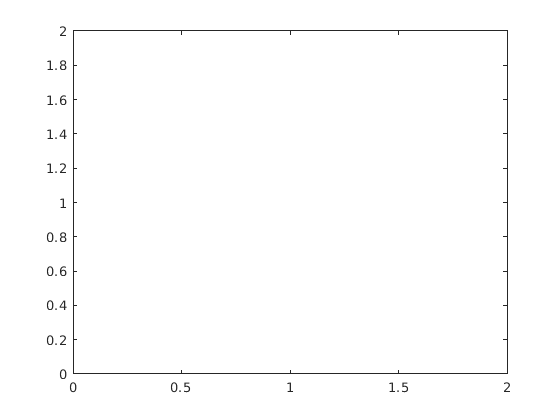

%Número de muestras a recordar
ind=70;

%Inicializacion de variables
dataMatrix = zeros(ind,254);
[READINGS] = initTables(ind);

%Limpia el buffer
flush(s)

%Cargar archivos dummy
%load RFData.mat

%Inicializar figuras
%Ploteos recientes
figure
recentReadings=plot(1);

## Lectura

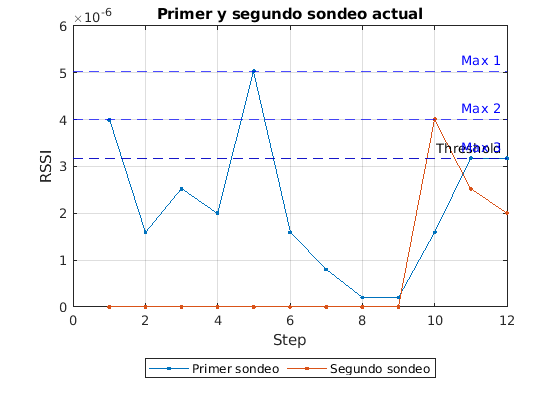

%while 1
%Mover todos las lecturas un espacio
dataMatrix=circshift(dataMatrix,1);
READINGS=circShiftAll(READINGS);

%Lectura del serial y llenado de tablas
dataMatrix(1,:)=read(s,254,'uint8');
READINGS=fillTables(dataMatrix,READINGS);

%Ploteo de lecturas
recentReadings=plotRecentReading(READINGS);

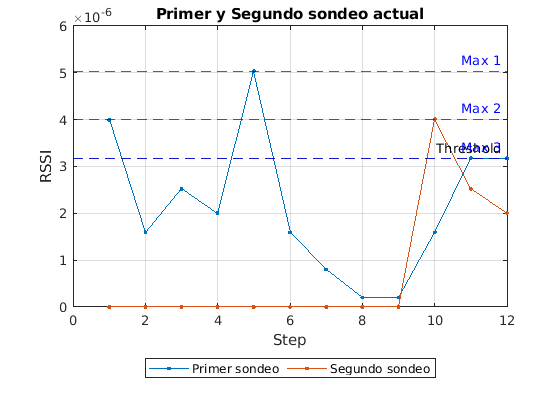

%end

## RSSI primer sondeo

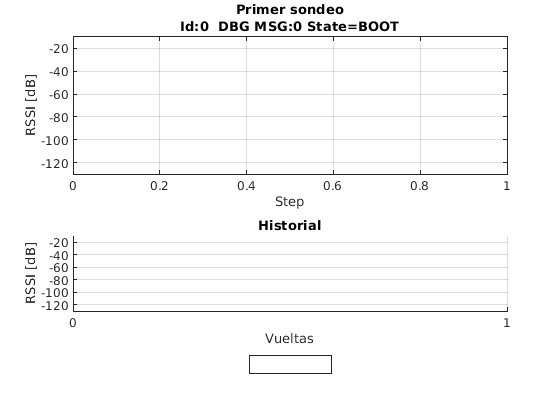

id_state=READINGS.NAVIGATION.CurrentState==1;
cmap=turbo(5);

%Lectura actual
figure
subplot(2,1,1)
plot(READINGS.RSSI_1Son.Step(1:12),READINGS.RSSI_1Son{1:12,["CH1" "CH2" "CH3" "CH4" "CH5"]},'.-')
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title(["Primer sondeo"; "Id:"+READINGS.CABECERA.Robot_ID(1)+"  DBG MSG:"+READINGS.CABECERA.DBG_MSG(1)+" State="+READINGS.STATES_DICTIONARY.Meaning(READINGS.NAVIGATION.CurrentState(1)==READINGS.STATES_DICTIONARY.Number)])
grid on
ax=gca;
ax.ColorOrder=cmap;

%Lecturas pasadas
subplot(2,1,2)
plot(READINGS.STAT_RSSI.Son1_median(id_state,:),'.-')
hold on
plot(READINGS.STAT_RSSI.Son1_1Q(id_state,:),'.--')
plot(READINGS.STAT_RSSI.Son1_3Q(id_state,:),'.--')
hold off
ylabel("RSSI [dB]")
xlabel("Vueltas")
title("Historial")
ylim([-130 -10])
grid on
ax=gca;
ax.ColorOrder=cmap;
ax.XTick=unique(round(ax.XTick));
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")


%xticks(unique(round(curtick)));
%end

## RSSI primer sondeo lineal

%Lectura actual
figure
subplot(2,1,1)   
plot(RSSI_1Son.Step(end-11:end),10.^(-RSSI_1Son{end-11:end,1:5}./10),'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI")
xlabel("Step")
title("Primer sondeo, última medida")
grid on
ax=gca;
ax.ColorOrder=cmap;


%Lecturas pasadas
%figure
subplot(2,1,2)
plot(10.^(-RSSI_1Son_statistics_median(id_dbgMsg,:)./10))
hold on
plot(10.^(-RSSI_1Son_statistics_3Q(id_dbgMsg,:)./10),'.--')
plot(10.^(-RSSI_1Son_statistics_1Q(id_dbgMsg,:)./10),'.--')
hold off
ylabel("RSSI ")
xlabel("Vueltas")
title("Historial primer sondeo")
grid on
ax=gca;
ax.ColorOrder=cmap;
%end

## RSSI primer sondeo log

%readingNo=max(RSSI.Reading);

readingNo=2;
index=RSSI_1Son.Sondeo==readingNo;

figure
subplot(2,1,1)
title("RSSI por canal")
plot(RSSI_1Son.Step(index),-RSSI_1Son{index,1:5},'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on
ax=gca;
ax.ColorOrder=cmap;


## RSSI primer sondeo lin

subplot(2,1,2)
plot(RSSI_1Son.Step(index),10.^((-RSSI_1Son{index,1:5})./10),'.-')
%legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI")
xlabel("Step")
%ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on
ax=gca;
ax.ColorOrder=cmap;

## RSSI segundo sondeo

%% Ploteo
cmap=turbo(5);
id_dbgMsg=NAVIGATION.CurrentState==1;

%Lectura actual
figure
subplot(2,1,1)
plot(RSSI_2Son.Step(end-11:end),-RSSI_2Son{end-11:end,1:5},'.-')
%colormap turbo
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("Segundo sondeo, última medida")
grid on
ax=gca;
ax.ColorOrder=cmap;

%Lecturas pasadas
subplot(2,1,2)
%figure
plot(-RSSI_2Son_statistics_median(id_dbgMsg,:),'.-')
hold on
plot(-RSSI_2Son_statistics_3Q(id_dbgMsg,:),'.--')
plot(-RSSI_2Son_statistics_1Q(id_dbgMsg,:),'.--')
hold off
ylabel("RSSI [dB]")
xlabel("Vueltas")
title("Historial segundo sondeo")
ylim([-130 -10])
grid on
ax=gca;
ax.ColorOrder=cmap;
%end

## RSSI Lineal

%Lectura actual
figure
%subplot(2,1,1)   
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(RSSI_2Son.Step(end-11:end),10.^(-RSSI_2Son{end-11:end,1:5}./10),'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI")
xlabel("Step")
%ylim([-130 -10])
title("Segundo sondeo, última medida")
grid on

%Lecturas pasadas
figure
%subplot(2,1,2)
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(10.^(-RSSI_2Son_statistics_median(id_dbgMsg,:)./10))
hold on
plot(10.^(-RSSI_2Son_statistics_3Q(id_dbgMsg,:)./10),'.--')
plot(10.^(-RSSI_2Son_statistics_1Q(id_dbgMsg,:)./10),'.--')
hold off
ylabel("RSSI ")
xlabel("Vueltas")
title("Historial segundo sondeo")
grid on
%ylim([-130 -10])
%end

## RSSI primer sondeo log

%readingNo=max(RSSI.Reading);

readingNo=2;
index=RSSI_2Son.Sondeo==readingNo;

figure
title("RSSI por canal")
plot(RSSI_2Son.Step(index),-RSSI_2Son{index,1:5},'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on



## RSSI primer segundo lin

%readingNo=2;
%index=RSSI_1Son.Sondeo==readingNo;
figure
    plot(RSSI_2Son.Step(index),10.^((-RSSI_2Son{index,1:5})./10),'.-')
    legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
    ylabel("RSSI")
    xlabel("Step")
    %ylim([-130 -10])
    title("RSSI Lectura "+readingNo)
    grid on


## Graficado

% %tiledlayout('flow')
% figure
% %nexttile
% plot(MOTORS{:,["Imot" "Isys"]},'o-')
% ylabel("[mA]")
% title("Consumo de corriente")
% legend(["Motores" "Sistema"])
% 


## Potencia en bobinas


% figure
% %plot(BOBINA{:,3:14},'o-')
% bar(BOBINA{:,3:15})
% ylabel("PSD Total [V^2/Hz]")
% title("Potencia espectral en bobinas")
% legend(["B"+(1:11) "Umbral"],'Location',"eastoutside")


## Cluster size

% figure
% bar(BOBINA{:,["ClusterSize" "BandsDetected" "BandsEmitted"]})
% legend(["ClusterSize" "BandsDetected" "BandsEmitted"])
% %Bands emited y detectadas
% %dec2bin(typecast(uint8(dataMatrix(i,71:72)),'uint16'),16)
% %el resultado se lee de derecha a izquierda
% %Cada bit representa una banda

## RSSI por lectura

% readingNo=max(RSSI.Reading);
% %index=RSSI.Reading==readingNo;
% figure
% %gscatter(RSSI.Angle,RSSI{:,1:5},RSSI.Angle)
% title("RSSI contra lectura")
% plot(RSSI.Reading,-RSSI{:,1:5},'-o')
% legend(["CH1" "CH2" "CH3" "CH4" "CH5"])
% ylabel("RSSI [dB]")
% xlabel("Angulo")
% ylim([-130 -10])
% title("RSSI Lectura "+readingNo)
